% NEC

% fn_cs2000 = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\0605\colorchecker_test_result_nec.mat';
% fn_cl500a = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\cl500a_0608\CL500a_nec.xlsx';
% fn_i1 = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\nec_i1_0608\i1data_nec.mat';
% fn_spyder = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\nec_0607\spyder_nec.mat';

% HP
fn_cs2000 = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\0605\colorchecker_test_result_hp.mat';
fn_cl500a = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\cl500a_0608\CL500a_hp.xlsx';
fn_i1 = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\hp_i1_0608\i1data_hp.mat';
fn_spyder = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\hp_0606\spyder0606.mat';

% Rift
fn_cs2000 = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\0605\colorchecker_test_result_rift.mat';
fn_cl500a = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\cl500a_0608\CL500a_rift.xlsx';
fn_i1 = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\rift_i1_0608\i1data_rift.mat';
fn_spyder = 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@LightSim\rift0607\spyder_rift.mat';

addpath('C:\Users\Wuchihlei\Documents\GitHub\color_performance_review')
addpath('C:\Users\Wuchihlei\Documents\GitHub\color_conversion')

data_cs2000 = DeviceData;
data_cl500a = DeviceData;
data_i1 = DeviceData;
data_lightsim = DeviceData;
data_spyder = DeviceData;

data_cs2000.construct_by_cs2000(fn_cs2000)
data_lightsim.construct_by_target(fn_cs2000)
data_cl500a.construct_by_CL500a(fn_cl500a)
data_i1.construct_by_i1(fn_i1)
data_spyder.construct_by_spyder(fn_spyder,3)

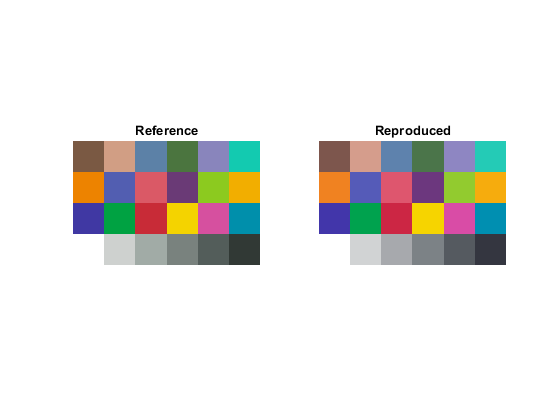

a=data_cs2000;
b=data_spyder;
cpr = ColorPerformanceReview;
clf; cpr.evaluate_visual(a,b);

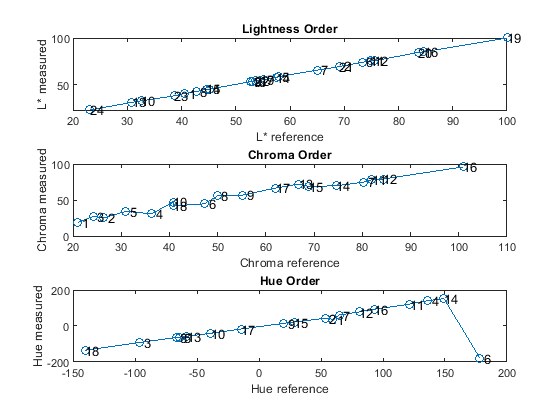

clf; cpr.evaluate_order(a,b);

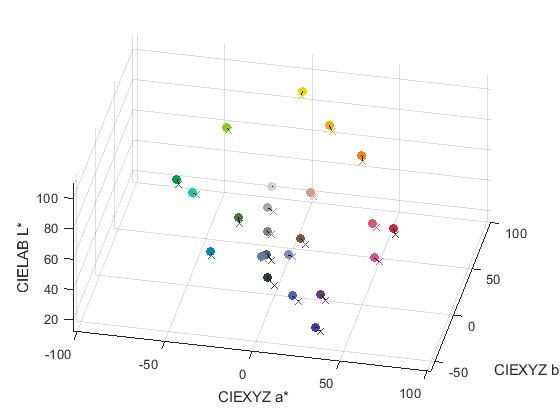

clf; cpr.show3dquiver(a,b); view([12 32])

dEmean = 3.2119

dEstd = 2.2718

dEmax = 9.8677

dEmin = 0.9903

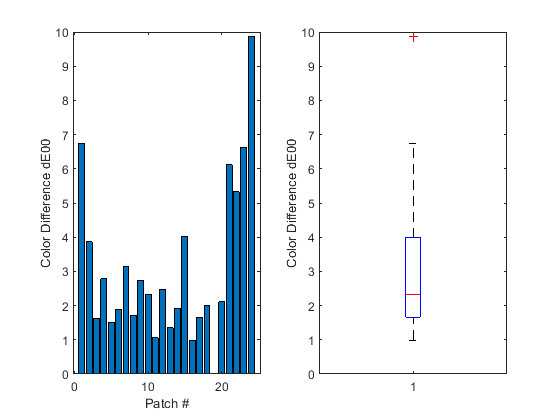

clf; cpr.evaluate_dE(a,b);

cce_measured = 0.9913

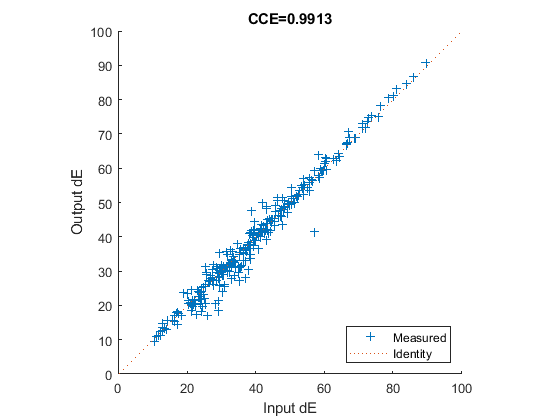

clf; cpr.evaluate_CCE(a,b);

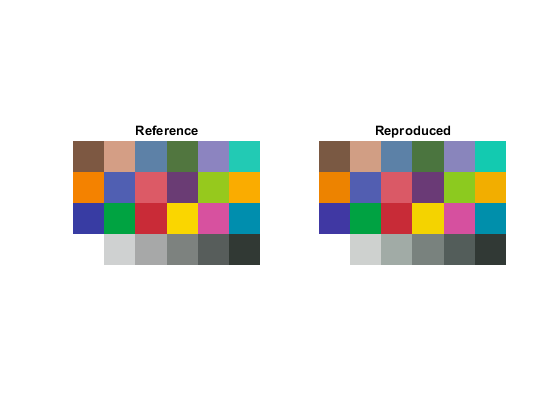

a=data_lightsim;
b=data_cs2000;
cpr = ColorPerformanceReview;
clf; cpr.evaluate_visual(a,b);

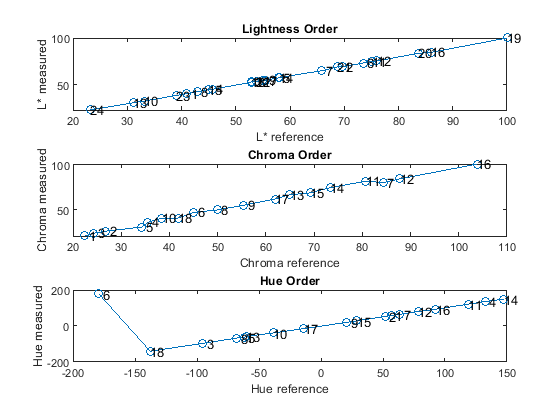

clf; cpr.evaluate_order(a,b);

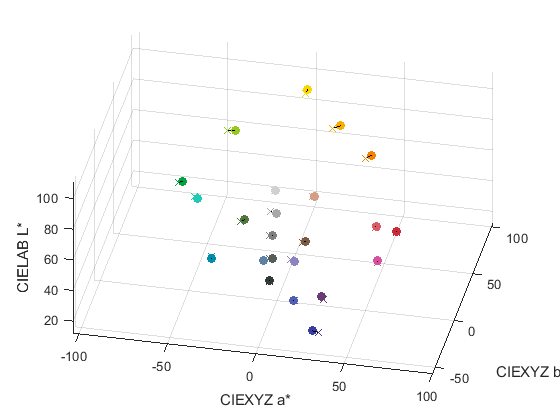

clf; cpr.show3dquiver(a,b); view([12 32])

ans = 'Adjusting reference by 1.000000X'

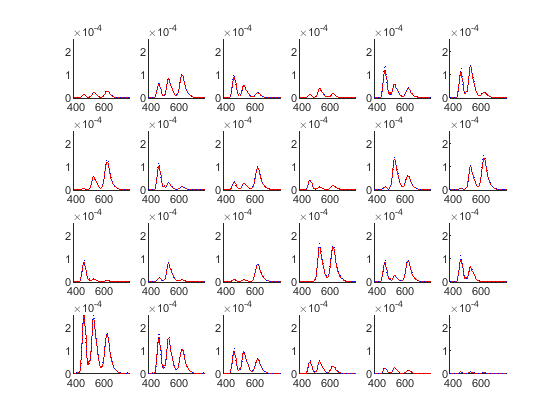

clf; b.compare_with_ref(a)

dEmean = 1.3860

dEstd = 0.9901

dEmax = 5.1441

dEmin = 0.3232

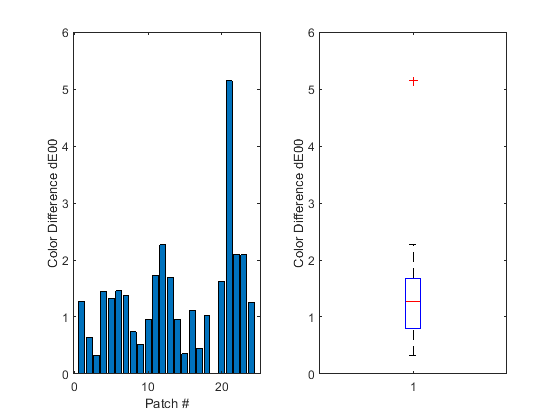

clf; cpr.evaluate_dE(a,b);

cce_measured = 1.0038

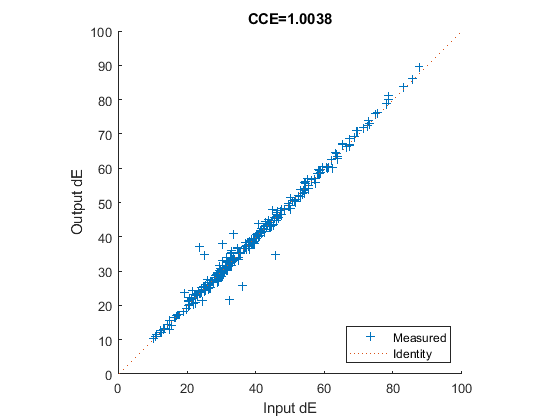

clf; cpr.evaluate_CCE(a,b);

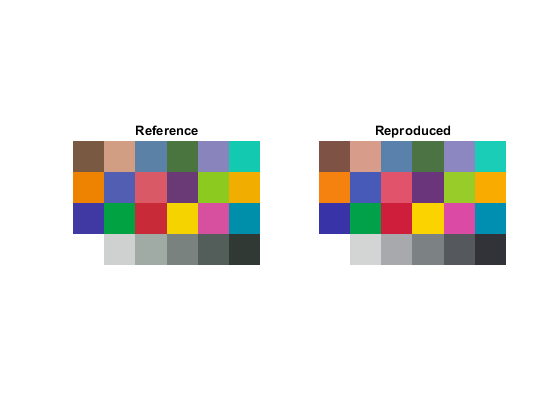

a=data_cs2000;
b=data_cl500a;
cpr = ColorPerformanceReview;
clf; cpr.evaluate_visual(a,b);

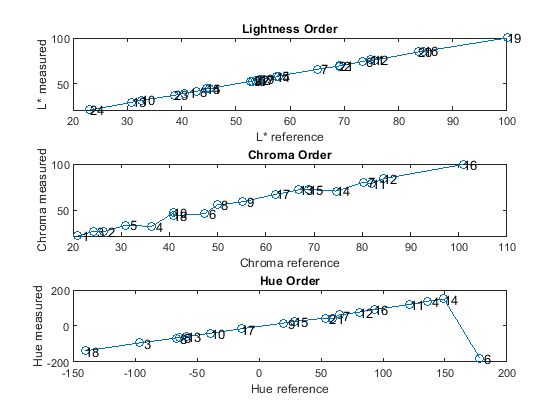

clf; cpr.evaluate_order(a,b);

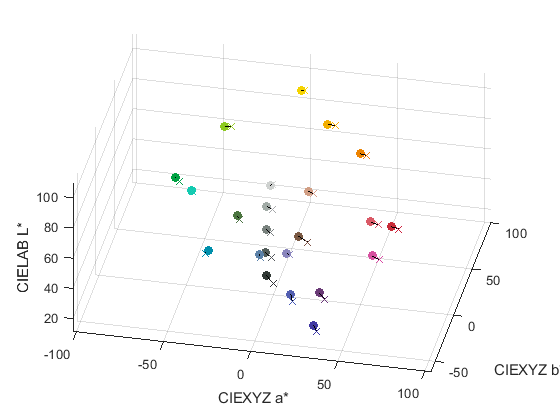

clf; cpr.show3dquiver(a,b); view([12 32])

ans = 'Adjusting reference by 1.000000X'

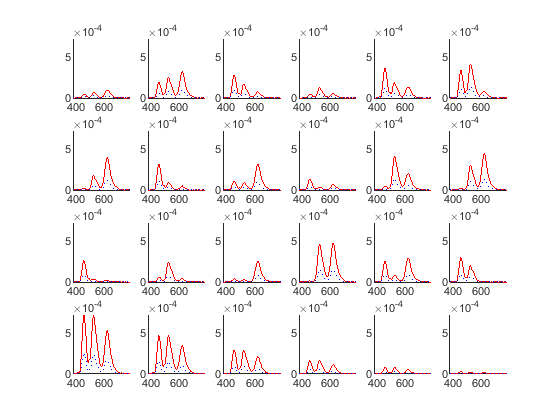

clf; b.compare_with_ref(a)

dEmean = 2.8375

dEstd = 1.9443

dEmax = 7.5717

dEmin = 1.0511

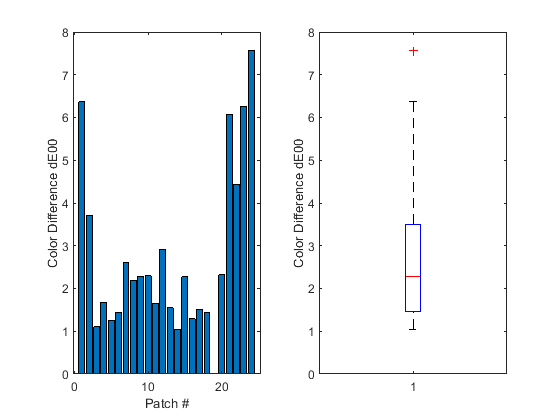

clf; cpr.evaluate_dE(a,b);

cce_measured = 1.0097

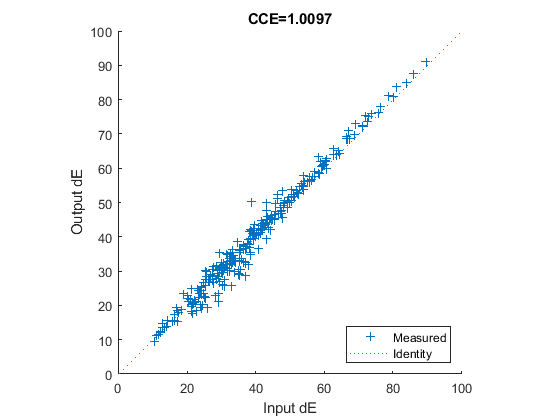

clf; cpr.evaluate_CCE(a,b);

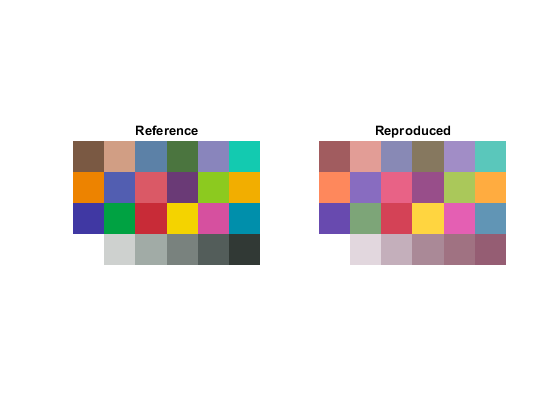

a=data_cs2000;
b=data_i1;
cpr = ColorPerformanceReview;
clf; cpr.evaluate_visual(a,b);

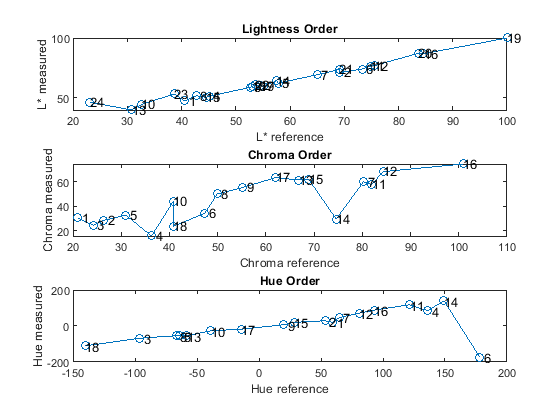

clf; cpr.evaluate_order(a,b);

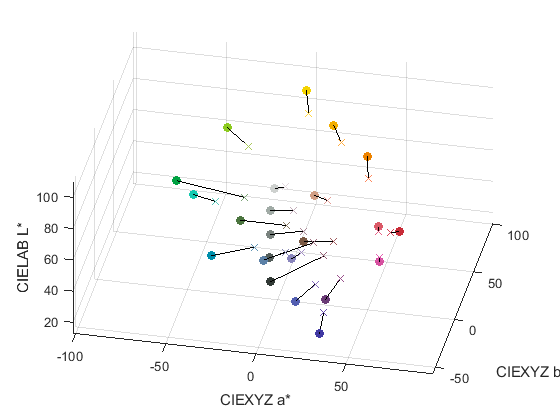

clf; cpr.show3dquiver(a,b); view([12 32])

ans = 'Adjusting reference by 1.000000X'

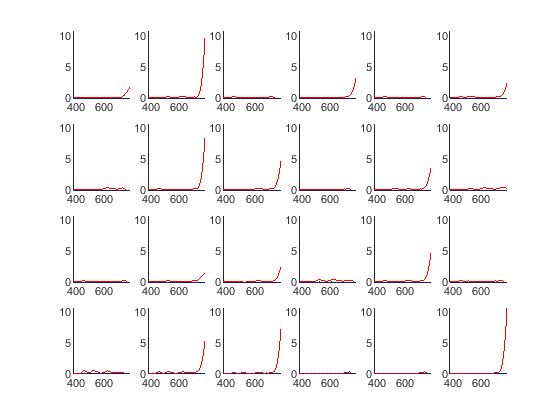

clf; b.compare_with_ref(a)

dEmean = 13.1666

dEstd = 8.0199

dEmax = 35.3036

dEmin = 5.0222

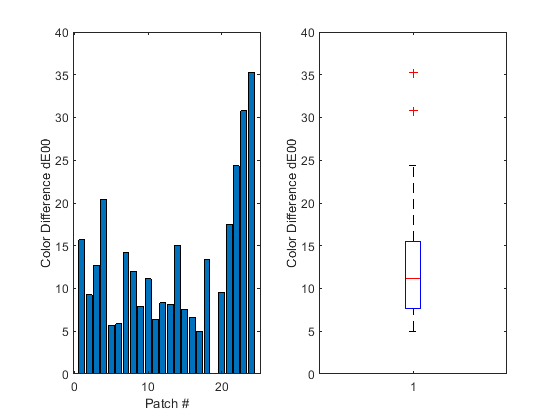

clf; cpr.evaluate_dE(a,b);

cce_measured = 0.8557

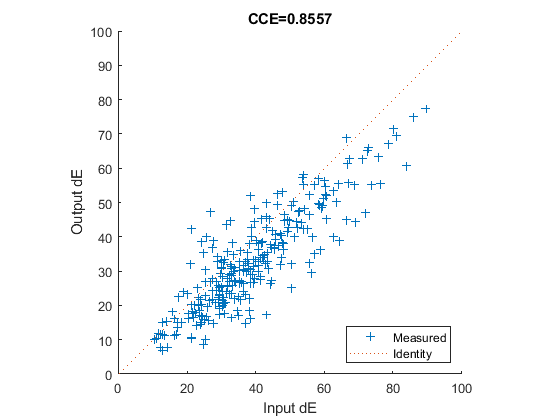

clf; cpr.evaluate_CCE(a,b);

function compare_dataspec (a,b)
cpr = ColorPerformanceReview;
figure; cpr.evaluate_visual(a,b);
cpr.evaluate_order(a,b);
cpr.show3dquiver(a,b); view([12 32])
b.compare_with_ref(a)
end